%lab 7&8
%Kun Zhang
%PHYS 434 A 
%Application Of Computers To Physical Measurement

h5disp('Heradata.h5','/','simple');

HDF5 Heradata.h5 
Group '/' 
    Group '/Data' 
        Dataset 'flags' 
            Size:  4x1024x1x82680
            MaxSize:  4x1024x1x82680
            Datatype:   H5T_ENUM
                Base Type:  H5T_STD_I8LE
                Member 'FALSE':  0
                Member 'TRUE':  1
            ChunkSize:  1x32x1x2584
            Filters:  unrecognized filter (lzf)
        Dataset 'nsamples' 
            Size:  4x1024x1x82680
            MaxSize:  4x1024x1x82680
            Datatype:   H5T_IEEE_F32LE (single)
            ChunkSize:  1x32x1x1292
            Filters:  unrecognized filter (lzf)
        Dataset 'visdata' 
            Size:  4x1024x1x82680
            MaxSize:  4x1024x1x82680
            Datatype:   H5T_COMPOUND
                Member 'r':  H5T_IEEE_F64LE (double)
                Member 'i':  H5T_IEEE_F64LE (double)
            ChunkSize:  1x16x1x646
            Filters:  none
    Group '/Header' 
        Dataset 'Nants_data' 
            Size:  scalar
            Dataty

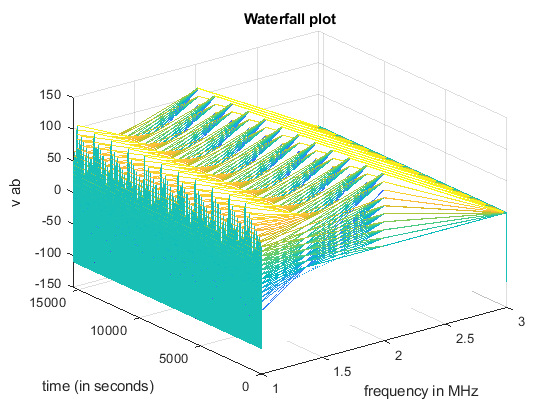

%due to unwieldly data, the data was retrieved using HDFview and
% exported to txt file

visdata=load('visdata(i).txt');
v_ab=h5read('Heradata.h5','/Header/uvw_array');
t_n=1:10:154450;
freq=h5read('Heradata.h5','/Header/freq_array');

%waterfall plot of v versus time and frequency.

figure (1);
waterfall(visdata);
title('Waterfall plot');
xlabel('frequency in MHz');
ylabel('time (in seconds)');
zlabel('v_ ab');

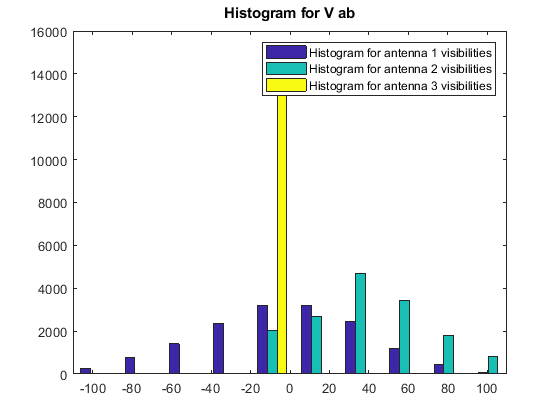

figure (2);
hist(visdata)
title('Histogram for V_ ab')
legend('Histogram for antenna 1 visibilities','Histogram for antenna 2 visibilities','Histogram for antenna 3 visibilities');
xlim([-110 110]);

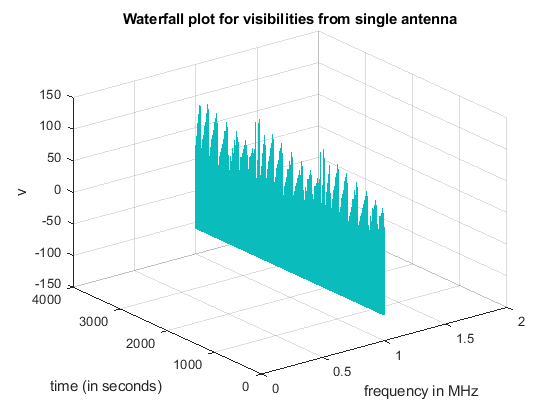

%single antenna pair plots.
%load antenna 1 visibilities


singleantennav_ab=load('singleantennavisibilitydata.txt');

%waterfall plot of antenna 1 visibilities.
figure (3)
waterfall(singleantennav_ab)
title('Waterfall plot for visibilities from single antenna')
xlabel('frequency in MHz');
ylabel('time (in seconds)');
zlabel('v')

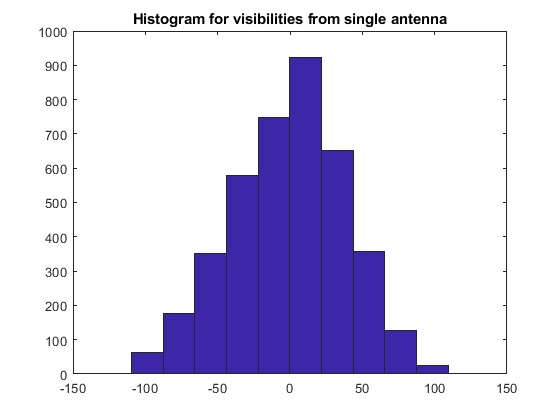


%Histogram of visibilities from single antenna.
%The shape of the Histogram can be seen to follow Poisson distribution.
%we are histogramming the magnitude so that we be in position to see
%the background distribution of the data (visibilities)
%through this process we can be able to determine the mean, median and standard deviation.
figure (4)
hist(singleantennav_ab);
title('Histogram for visibilities from single antenna')

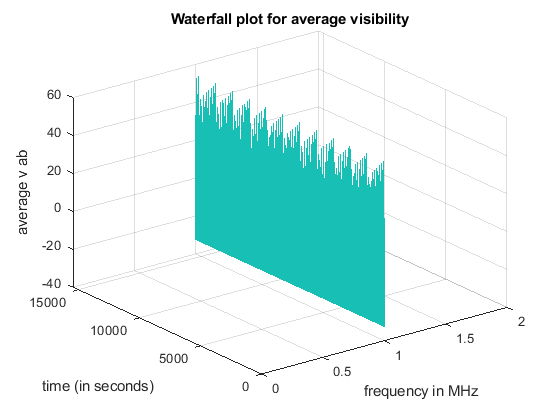

%average visbility plots
%load and read average visbilities for all antenna pairs.

averagevisibility=load('averagevisibility.txt');
%plot waterfall

waterfall(averagevisibility)
title('Waterfall plot for average visibility');
xlabel('frequency in MHz');
ylabel('time (in seconds)');
zlabel('average v_ ab');

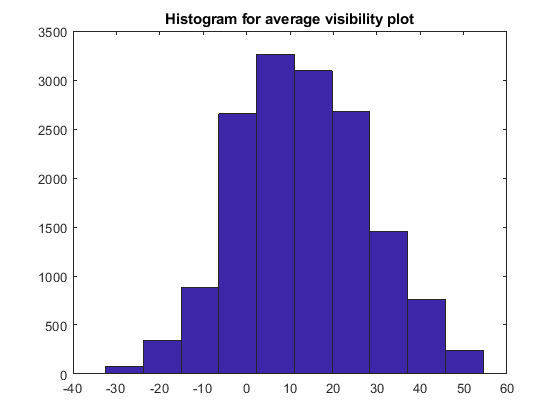


%histogram plot
hist(averagevisibility)
title('Histogram for average visibility plot')

% exploring.
%the distribution is not centered at zero therefore it is useful to subtract average value (global value).
















